close all
clear all

% Función de transferencia de posición del motor
G = tf(273,[1  4.112 0]); % Planta del laboratorio pasado + integrador

%Parámetros de diseño
Tes = 4;
Mp = 0.2; % 20% < 40%
% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -1.0000 + 1.9520i

s2 = -sigma-wd*1j

s2 = -1.0000 - 1.9520i


so = -2*sigma

so = -2

% Controlador
Td = -1/(2*so)

Td = 0.2500

Ti = 4*Td

Ti = 1

Gc_p = tf([Td*Ti Ti 1], [Ti 0])


Gc_p =
 
  0.25 s^2 + s + 1
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
  68.25 s^2 + 273 s + 273
  -----------------------
      s^3 + 4.112 s^2
 
Continuous-time transfer function.
Model Properties


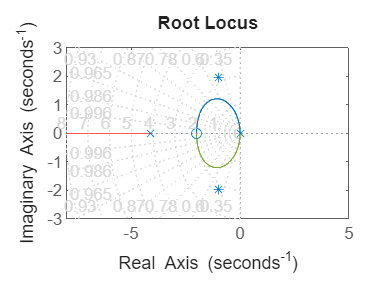

figure(1)
rlocus(Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
axis([-8 5 -3  3])
hold off

% K = 0.0669
Kp=0.0669;
%En lazo cerrado
Glc = feedback(Kp*Gol,1)


Glc =
 
     4.566 s^2 + 18.26 s + 18.26
  ---------------------------------
  s^3 + 8.678 s^2 + 18.26 s + 18.26
 
Continuous-time transfer function.
Model Properties


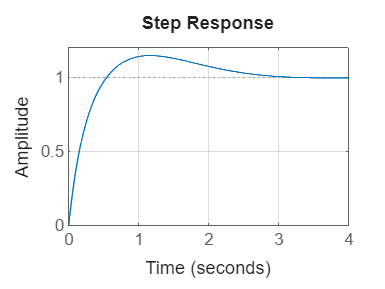


figure(2)
step(Glc);
grid on

% Tiempo de subida
Tr = 0.606 - 0.0268

Tr = 0.5792

T = 0.05;